%calculating the mean first passage time using Gillespie simulations
%to investigate multiple invader-substrate mismatches on RNA/DNA toehold
%exchange kinetics including spontaneous incumbent dissociation 

b = 20 %define branch migration domain length 

b = 20

g2 = 2 %define incumbent toehold length

g2 = 2

g = 3 %define invader toehold length

g = 3

bg2 = b + g2 %define branch migration domain + incumbent toehold length

bg2 = 22


m = zeros(1, 4) 

m =      0     0     0     0


m(1) = 2 %define position of first mismatch

m =      2     0     0     0



R = 1.987/1000 % universal gas constant in kcal/K/mol

R = 0.0020

temp = 298.15 %temperature in K

temp = 298.1500

%free energy parameters
dGassoc = 2.6*R*temp

dGassoc = 1.5403

dGbp = -2.52*R*temp

dGbp = -1.4929

dGp = 3.6*R*temp

dGp = 2.1327

dGmm = 1*R*temp

dGmm = 0.5924

dGrd = -1*R*temp

dGrd = -0.5924

dGbm = 7.4*R*temp 

dGbm = 4.3839

%absolute rate constant
k_bp = 5.4*10^7

k_bp = 54000000

N = 10 %number of simulations

N = 10

avr_first_pass_time = zeros(4,20)

avr_first_pass_time =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ind_first_pass_time = zeros(4, 20, N)

ind_first_pass_time = ind_first_pass_time(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ind_first_pass_time(:,:,2) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0   

k_eff = zeros(4, 20)

k_eff =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ind_k_eff = zeros(4, 20, N)

ind_k_eff = ind_k_eff(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ind_k_eff(:,:,2) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

std_err_fpt = zeros(4, 20)

std_err_fpt =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


std_err_k_eff = zeros(4, 20)

std_err_k_eff =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


std_err_log_k = zeros(4,20)

std_err_log_k =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



%loop through number of mismatches
for ind = 2:5 
    %loop through position of mismatches
    for pos = m(ind-1)+1:b
        m(ind) = pos
    
        %define forward and reverse transition rates
        k_AA = 0;
        k_AB1 = k_bp * exp(-dGassoc/(R*temp)) * (5*10^-8)
        k_B1A = k_bp * exp((dGbp + dGrd)/(R*temp))
        k_BC1ij = k_bp;
        k_BC1ji = k_bp * exp((dGbp + dGrd)/(R*temp))
        k_C1f = k_bp * exp(-(dGbm + dGp)/(R*temp))
        k_Cf = k_bp * exp(-dGbm/(R*temp))
        k_Cr = k_bp * exp(-(dGbm - dGrd)/(R*temp))
        k_Crm = k_bp * exp((dGmm - dGbm + dGrd)/(R*temp)) %I have added the + dGrd
        k_Crm_end = k_bp * exp((dGmm - dGbm - dGp + dGrd)/(R*temp)) %I have added the + dGrd
        k_DC = k_bp * exp(-(dGbm + dGp - dGrd)/(R*temp))
        k_DEij = k_bp * exp(dGbp/(R*temp));
        k_DEji = k_bp;
        k_EF = k_bp * exp(dGbp/(R*temp));
        k_FE = 0
        k_FF = 1   
    
    
        first_pass_time = zeros(1,N)
    
        %create arrays of forward and reverse transition rates
        Kf = [k_AB1, k_BC1ij, repmat(k_BC1ij, [1, g-2]), k_C1f, repmat(k_Cf, [1, b-1]), repmat(k_DEij, [1, g2-1]), k_EF, k_FF]
        Kb = [k_AA, k_B1A, repmat(k_BC1ji, [1, g-2]), k_BC1ji, repmat(k_Cr, [1, b-1]), k_DC, repmat(k_DEji, [1, g2-1]), k_FE]
        for no = 1:ind
            if m(no) == b
                Kb(g + m(no) + 1) = k_Crm_end  
            else
                Kb(g + m(no) + 1) = k_Crm 
            end
        end
        
        %define spontaneous incumbent dissociation rate
        Koff = [repmat(0, [1, g+1])];
        for n = bg2-1:-1:g2+1
            Koff = horzcat(Koff, [k_bp*exp(-(n*(-dGbp))/(R*temp))]);
        end
        Koff = horzcat(Koff, [repmat(0, [1, g2+1])])      
    
        totalrate = Kf + Kb + Koff; %define total rate
        Pf = Kf./totalrate; %probability of forward transition
        Poff = Koff./totalrate; %probability of spontaneous incumbent dissociation
        Pb = 1- (Pf + Poff); %probability of reverse transition
        %loop through simulations
        for n = 1:N 
            state = 1; %initial state
            t = 0; %initial time
            %restrict to possible states
            while (state >=1 && state < (2 + g + b + g2)) 
                t = t - (1/totalrate(state))*log(rand()); %calculate time for transition
                prob = rand();
                %select transition
                if prob <= Pf(state) 
                    state = state +1; %update state forward
                elseif prob > Pf(state) && prob < Pf (state) + Poff(state)
                    state = 2 + g + b + g2; %update state for spontanoeous incumbent dissociation
                else 
                    state = state -1; %update state backward
                end
            end
            first_pass_time(n) =  t; 
            ind_first_pass_time(ind-1, pos ,n) = first_pass_time(n);
            ind_k_eff(ind-1, pos,n) = 1/(first_pass_time(n)*(5*10^-8));
        end
        std_err_fpt(ind-1, pos) = std(ind_first_pass_time(ind-1, pos, :))/sqrt(N); %calculate standard error
        std_err_k_eff(ind-1, pos) = std(ind_k_eff(ind-1, pos, :))/sqrt(N);
        std_err_log_k(ind-1, pos) = std(log10(ind_k_eff(ind-1, pos,:))/sqrt(N));
        avr_first_pass_time(ind-1, pos) = mean(first_pass_time) %calculate average first passage time
        k_eff(ind-1, pos) = 1/(mean(first_pass_time)*(5*10^-8)) %calculate effective rate constant
    end
    m(ind) = m(ind-1) + 3; %introduce spaces between mismatches
end

m =      2     3     0     0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_Crm = 8.9724e+04

k_Crm_end = 2.4516e+03

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf = 	1.0e+07 *

    0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb = 	1.0e+07 *

         0    0.1598    0.1598    0.1598    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb = 	1.0e+07 *

         0    0.1598    0.1598    0.0090    0.0012    0.0090    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb = 	1.0e+07 *

         0    0.1598    0.1598    0.0090    0.0012    0.0090    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Koff = 	1.0e+04 *

         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =          0         0    7.6814         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff = 	1.0e+06 *

         0         0    2.6037         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     4     0     0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_Crm = 8.9724e+04

k_Crm_end = 2.4516e+03

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf = 	1.0e+07 *

    0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb = 	1.0e+07 *

         0    0.1598    0.1598    0.1598    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb = 	1.0e+07 *

         0    0.1598    0.1598    0.0090    0.0012    0.0090    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb = 	1.0e+07 *

         0    0.1598    0.1598    0.0090    0.0012    0.0090    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Koff = 	1.0e+04 *

         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =          0         0    7.6814   11.3816         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff = 	1.0e+06 *

         0         0    2.6037    1.7572         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5     0     0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_Crm = 8.9724e+04

k_Crm_end = 2.4516e+03

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf = 	1.0e+07 *

    0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb = 	1.0e+07 *

         0    0.1598    0.1598    0.1598    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb = 	1.0e+07 *

         0    0.1598    0.1598    0.0090    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb = 	1.0e+07 *

         0    0.1598    0.1598    0.0090    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Koff = 	1.0e+04 *

         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =          0         0    7.6814   11.3816    4.7032         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff = 	1.0e+06 *

         0         0    2.6037    1.7572    4.2524         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     6     0     0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_Crm = 8.9724e+04

k_Crm_end = 2.4516e+03

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf = 	1.0e+07 *

    0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb = 	1.0e+07 *

         0    0.1598    0.1598    0.1598    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb = 	1.0e+07 *

         0    0.1598    0.1598    0.0090    0.0012    0.0090    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb = 	1.0e+07 *

         0    0.1598    0.1598    0.0090    0.0012    0.0090    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Koff = 	1.0e+04 *

         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =          0         0    7.6814   11.3816    4.7032    8.8962         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff = 	1.0e+06 *

         0         0    2.6037    1.7572    4.2524    2.2482         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     7     0     0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_Crm = 8.9724e+04

k_Crm_end = 2.4516e+03

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf = 	1.0e+07 *

    0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb = 	1.0e+07 *

         0    0.1598    0.1598    0.1598    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb = 	1.0e+07 *

         0    0.1598    0.1598    0.0090    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb = 	1.0e+07 *

         0    0.1598    0.1598    0.0090    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Koff = 	1.0e+04 *

         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =          0         0    7.6814   11.3816    4.7032    8.8962    5.0967         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =          0         0    2.6037    1.7572    4.2524    2.2482    3.9241         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     8     0     0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_Crm = 8.9724e+04

k_Crm_end = 2.4516e+03

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.0090    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.0090    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =          0         0    7.6814   11.3816    4.7032    8.8962    5.0967    5.2234         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =          0         0    2.6037    1.7572    4.2524    2.2482    3.9241    3.8289         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     9     0     0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_Crm = 8.9724e+04

k_Crm_end = 2.4516e+03

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.0090    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.0090    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =          0         0    7.6814   11.3816    4.7032    8.8962    5.0967    5.2234    6.6504         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =          0         0    2.6037    1.7572    4.2524    2.2482    3.9241    3.8289    3.0073         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2    10     0     0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_Crm = 8.9724e+04

k_Crm_end = 2.4516e+03

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.0090    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.0090    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =          0         0    7.6814   11.3816    4.7032    8.8962    5.0967    5.2234    6.6504    4.4268         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =          0         0    2.6037    1.7572    4.2524    2.2482    3.9241    3.8289    3.0073    4.5179         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2    11     0     0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_Crm = 8.9724e+04

k_Crm_end = 2.4516e+03

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.0090    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.0090    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =          0         0    7.6814   11.3816    4.7032    8.8962    5.0967    5.2234    6.6504    4.4268   11.6625         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =          0         0    2.6037    1.7572    4.2524    2.2482    3.9241    3.8289    3.0073    4.5179    1.7149         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2    12     0     0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_Crm = 8.9724e+04

k_Crm_end = 2.4516e+03

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.0090    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.0090    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =          0         0    7.6814   11.3816    4.7032    8.8962    5.0967    5.2234    6.6504    4.4268   11.6625    5.4204         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =          0         0    2.6037    1.7572    4.2524    2.2482    3.9241    3.8289    3.0073    4.5179    1.7149    3.6898         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2    13     0     0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_Crm = 8.9724e+04

k_Crm_end = 2.4516e+03

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.0090    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.0090    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =          0         0    7.6814   11.3816    4.7032    8.8962    5.0967    5.2234    6.6504    4.4268   11.6625    5.4204    5.0048         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =          0         0    2.6037    1.7572    4.2524    2.2482    3.9241    3.8289    3.0073    4.5179    1.7149    3.6898    3.9962         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2    14     0     0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_Crm = 8.9724e+04

k_Crm_end = 2.4516e+03

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.0090    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.0090    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =          0         0    7.6814   11.3816    4.7032    8.8962    5.0967    5.2234    6.6504    4.4268   11.6625    5.4204    5.0048    6.1915         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =          0         0    2.6037    1.7572    4.2524    2.2482    3.9241    3.8289    3.0073    4.5179    1.7149    3.6898    3.9962    3.2303         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2    15     0     0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_Crm = 8.9724e+04

k_Crm_end = 2.4516e+03

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.0090    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.0090    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =          0         0    7.6814   11.3816    4.7032    8.8962    5.0967    5.2234    6.6504    4.4268   11.6625    5.4204    5.0048    6.1915    7.4548         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =          0         0    2.6037    1.7572    4.2524    2.2482    3.9241    3.8289    3.0073    4.5179    1.7149    3.6898    3.9962    3.2303    2.6828         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2    16     0     0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_Crm = 8.9724e+04

k_Crm_end = 2.4516e+03

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.0090    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.0090    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0000    5.4000         0


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =          0         0    7.6814   11.3816    4.7032    8.8962    5.0967    5.2234    6.6504    4.4268   11.6625    5.4204    5.0048    6.1915    7.4548    4.7247         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =          0         0    2.6037    1.7572    4.2524    2.2482    3.9241    3.8289    3.0073    4.5179    1.7149    3.6898    3.9962    3.2303    2.6828    4.2330         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2    17     0     0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_Crm = 8.9724e+04

k_Crm_end = 2.4516e+03

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.0090    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.0090    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0000    5.4000         0


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =          0         0    7.6814   11.3816    4.7032    8.8962    5.0967    5.2234    6.6504    4.4268   11.6625    5.4204    5.0048    6.1915    7.4548    4.7247    6.7371         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =          0         0    2.6037    1.7572    4.2524    2.2482    3.9241    3.8289    3.0073    4.5179    1.7149    3.6898    3.9962    3.2303    2.6828    4.2330    2.9687         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2    18     0     0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_Crm = 8.9724e+04

k_Crm_end = 2.4516e+03

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.0090    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.0090    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0000    5.4000         0


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =          0         0    7.6814   11.3816    4.7032    8.8962    5.0967    5.2234    6.6504    4.4268   11.6625    5.4204    5.0048    6.1915    7.4548    4.7247    6.7371    6.5317         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =          0         0    2.6037    1.7572    4.2524    2.2482    3.9241    3.8289    3.0073    4.5179    1.7149    3.6898    3.9962    3.2303    2.6828    4.2330    2.9687    3.0620         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2    19     0     0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_Crm = 8.9724e+04

k_Crm_end = 2.4516e+03

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.0090    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.0090    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0000    5.4000         0


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =          0         0    7.6814   11.3816    4.7032    8.8962    5.0967    5.2234    6.6504    4.4268   11.6625    5.4204    5.0048    6.1915    7.4548    4.7247    6.7371    6.5317    4.6591         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =          0         0    2.6037    1.7572    4.2524    2.2482    3.9241    3.8289    3.0073    4.5179    1.7149    3.6898    3.9962    3.2303    2.6828    4.2330    2.9687    3.0620    4.2927         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2    20     0     0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_Crm = 8.9724e+04

k_Crm_end = 2.4516e+03

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.0090    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    5.4000         0


Kb =          0    0.1598    0.1598    0.0090    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0002    5.4000         0


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =          0         0    7.6814   11.3816    4.7032    8.8962    5.0967    5.2234    6.6504    4.4268   11.6625    5.4204    5.0048    6.1915    7.4548    4.7247    6.7371    6.5317    4.6591    8.8585
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =          0         0    2.6037    1.7572    4.2524    2.2482    3.9241    3.8289    3.0073    4.5179    1.7149    3.6898    3.9962    3.2303    2.6828    4.2330    2.9687    3.0620    4.2927    2.2577
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5     6     0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_Crm = 8.9724e+04

k_Crm_end = 2.4516e+03

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.0090    0.0012    0.0090    0.0012    0.0012    0.0090    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.0090    0.0012    0.0090    0.0012    0.0012    0.0090    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.0090    0.0012    0.0090    0.0012    0.0012    0.0090    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =          0         0    7.6814   11.3816    4.7032    8.8962    5.0967    5.2234    6.6504    4.4268   11.6625    5.4204    5.0048    6.1915    7.4548    4.7247    6.7371    6.5317    4.6591    8.8585
         0         0         0         0         0    5.3735         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =          0         0    2.6037    1.7572    4.2524    2.2482    3.9241    3.8289    3.0073    4.5179    1.7149    3.6898    3.9962    3.2303    2.6828    4.2330    2.9687    3.0620    4.2927    2.2577
         0         0         0         0         0    3.7219         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5     7     0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_Crm = 8.9724e+04

k_Crm_end = 2.4516e+03

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.0090    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.0090    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.0090    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =          0         0    7.6814   11.3816    4.7032    8.8962    5.0967    5.2234    6.6504    4.4268   11.6625    5.4204    5.0048    6.1915    7.4548    4.7247    6.7371    6.5317    4.6591    8.8585
         0         0         0         0         0    5.3735    5.7098         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =          0         0    2.6037    1.7572    4.2524    2.2482    3.9241    3.8289    3.0073    4.5179    1.7149    3.6898    3.9962    3.2303    2.6828    4.2330    2.9687    3.0620    4.2927    2.2577
         0         0         0         0         0    3.7219    3.5027         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5     8     0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_Crm = 8.9724e+04

k_Crm_end = 2.4516e+03

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.0090    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.0090    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.0090    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =          0         0    7.6814   11.3816    4.7032    8.8962    5.0967    5.2234    6.6504    4.4268   11.6625    5.4204    5.0048    6.1915    7.4548    4.7247    6.7371    6.5317    4.6591    8.8585
         0         0         0         0         0    5.3735    5.7098    9.5575         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =          0         0    2.6037    1.7572    4.2524    2.2482    3.9241    3.8289    3.0073    4.5179    1.7149    3.6898    3.9962    3.2303    2.6828    4.2330    2.9687    3.0620    4.2927    2.2577
         0         0         0         0         0    3.7219    3.5027    2.0926         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5     9     0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_Crm = 8.9724e+04

k_Crm_end = 2.4516e+03

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.0090    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.0090    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.0090    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =          0         0    7.6814   11.3816    4.7032    8.8962    5.0967    5.2234    6.6504    4.4268   11.6625    5.4204    5.0048    6.1915    7.4548    4.7247    6.7371    6.5317    4.6591    8.8585
         0         0         0         0         0    5.3735    5.7098    9.5575    5.6153         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =          0         0    2.6037    1.7572    4.2524    2.2482    3.9241    3.8289    3.0073    4.5179    1.7149    3.6898    3.9962    3.2303    2.6828    4.2330    2.9687    3.0620    4.2927    2.2577
         0         0         0         0         0    3.7219    3.5027    2.0926    3.5617         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5    10     0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_Crm = 8.9724e+04

k_Crm_end = 2.4516e+03

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.0090    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.0090    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.0090    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =          0         0    7.6814   11.3816    4.7032    8.8962    5.0967    5.2234    6.6504    4.4268   11.6625    5.4204    5.0048    6.1915    7.4548    4.7247    6.7371    6.5317    4.6591    8.8585
         0         0         0         0         0    5.3735    5.7098    9.5575    5.6153    6.7693         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =          0         0    2.6037    1.7572    4.2524    2.2482    3.9241    3.8289    3.0073    4.5179    1.7149    3.6898    3.9962    3.2303    2.6828    4.2330    2.9687    3.0620    4.2927    2.2577
         0         0         0         0         0    3.7219    3.5027    2.0926    3.5617    2.9545         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5    11     0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_Crm = 8.9724e+04

k_Crm_end = 2.4516e+03

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.0090    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.0090    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.0090    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =          0         0    7.6814   11.3816    4.7032    8.8962    5.0967    5.2234    6.6504    4.4268   11.6625    5.4204    5.0048    6.1915    7.4548    4.7247    6.7371    6.5317    4.6591    8.8585
         0         0         0         0         0    5.3735    5.7098    9.5575    5.6153    6.7693    9.4154         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =          0         0    2.6037    1.7572    4.2524    2.2482    3.9241    3.8289    3.0073    4.5179    1.7149    3.6898    3.9962    3.2303    2.6828    4.2330    2.9687    3.0620    4.2927    2.2577
         0         0         0         0         0    3.7219    3.5027    2.0926    3.5617    2.9545    2.1242         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5    12     0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_Crm = 8.9724e+04

k_Crm_end = 2.4516e+03

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.0090    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.0090    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.0090    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =          0         0    7.6814   11.3816    4.7032    8.8962    5.0967    5.2234    6.6504    4.4268   11.6625    5.4204    5.0048    6.1915    7.4548    4.7247    6.7371    6.5317    4.6591    8.8585
         0         0         0         0         0    5.3735    5.7098    9.5575    5.6153    6.7693    9.4154    9.6570         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =          0         0    2.6037    1.7572    4.2524    2.2482    3.9241    3.8289    3.0073    4.5179    1.7149    3.6898    3.9962    3.2303    2.6828    4.2330    2.9687    3.0620    4.2927    2.2577
         0         0         0         0         0    3.7219    3.5027    2.0926    3.5617    2.9545    2.1242    2.0710         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5    13     0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_Crm = 8.9724e+04

k_Crm_end = 2.4516e+03

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.0090    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.0090    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.0090    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =          0         0    7.6814   11.3816    4.7032    8.8962    5.0967    5.2234    6.6504    4.4268   11.6625    5.4204    5.0048    6.1915    7.4548    4.7247    6.7371    6.5317    4.6591    8.8585
         0         0         0         0         0    5.3735    5.7098    9.5575    5.6153    6.7693    9.4154    9.6570    5.5343         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =          0         0    2.6037    1.7572    4.2524    2.2482    3.9241    3.8289    3.0073    4.5179    1.7149    3.6898    3.9962    3.2303    2.6828    4.2330    2.9687    3.0620    4.2927    2.2577
         0         0         0         0         0    3.7219    3.5027    2.0926    3.5617    2.9545    2.1242    2.0710    3.6138         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5    14     0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_Crm = 8.9724e+04

k_Crm_end = 2.4516e+03

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.0090    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.0090    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.0090    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =          0         0    7.6814   11.3816    4.7032    8.8962    5.0967    5.2234    6.6504    4.4268   11.6625    5.4204    5.0048    6.1915    7.4548    4.7247    6.7371    6.5317    4.6591    8.8585
         0         0         0         0         0    5.3735    5.7098    9.5575    5.6153    6.7693    9.4154    9.6570    5.5343    7.5090         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =          0         0    2.6037    1.7572    4.2524    2.2482    3.9241    3.8289    3.0073    4.5179    1.7149    3.6898    3.9962    3.2303    2.6828    4.2330    2.9687    3.0620    4.2927    2.2577
         0         0         0         0         0    3.7219    3.5027    2.0926    3.5617    2.9545    2.1242    2.0710    3.6138    2.6635         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5    15     0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_Crm = 8.9724e+04

k_Crm_end = 2.4516e+03

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.0090    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.0090    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.0090    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =          0         0    7.6814   11.3816    4.7032    8.8962    5.0967    5.2234    6.6504    4.4268   11.6625    5.4204    5.0048    6.1915    7.4548    4.7247    6.7371    6.5317    4.6591    8.8585
         0         0         0         0         0    5.3735    5.7098    9.5575    5.6153    6.7693    9.4154    9.6570    5.5343    7.5090    7.2892         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =          0         0    2.6037    1.7572    4.2524    2.2482    3.9241    3.8289    3.0073    4.5179    1.7149    3.6898    3.9962    3.2303    2.6828    4.2330    2.9687    3.0620    4.2927    2.2577
         0         0         0         0         0    3.7219    3.5027    2.0926    3.5617    2.9545    2.1242    2.0710    3.6138    2.6635    2.7438         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5    16     0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_Crm = 8.9724e+04

k_Crm_end = 2.4516e+03

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.0090    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.0090    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.0090    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0000    5.4000         0


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =          0         0    7.6814   11.3816    4.7032    8.8962    5.0967    5.2234    6.6504    4.4268   11.6625    5.4204    5.0048    6.1915    7.4548    4.7247    6.7371    6.5317    4.6591    8.8585
         0         0         0         0         0    5.3735    5.7098    9.5575    5.6153    6.7693    9.4154    9.6570    5.5343    7.5090    7.2892    7.3372         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =          0         0    2.6037    1.7572    4.2524    2.2482    3.9241    3.8289    3.0073    4.5179    1.7149    3.6898    3.9962    3.2303    2.6828    4.2330    2.9687    3.0620    4.2927    2.2577
         0         0         0         0         0    3.7219    3.5027    2.0926    3.5617    2.9545    2.1242    2.0710    3.6138    2.6635    2.7438    2.7258         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5    17     0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_Crm = 8.9724e+04

k_Crm_end = 2.4516e+03

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.0090    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.0090    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.0090    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0000    5.4000         0


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =          0         0    7.6814   11.3816    4.7032    8.8962    5.0967    5.2234    6.6504    4.4268   11.6625    5.4204    5.0048    6.1915    7.4548    4.7247    6.7371    6.5317    4.6591    8.8585
         0         0         0         0         0    5.3735    5.7098    9.5575    5.6153    6.7693    9.4154    9.6570    5.5343    7.5090    7.2892    7.3372    9.2258         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =          0         0    2.6037    1.7572    4.2524    2.2482    3.9241    3.8289    3.0073    4.5179    1.7149    3.6898    3.9962    3.2303    2.6828    4.2330    2.9687    3.0620    4.2927    2.2577
         0         0         0         0         0    3.7219    3.5027    2.0926    3.5617    2.9545    2.1242    2.0710    3.6138    2.6635    2.7438    2.7258    2.1678         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5    18     0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_Crm = 8.9724e+04

k_Crm_end = 2.4516e+03

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.0090    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.0090    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.0090    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0000    5.4000         0


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =          0         0    7.6814   11.3816    4.7032    8.8962    5.0967    5.2234    6.6504    4.4268   11.6625    5.4204    5.0048    6.1915    7.4548    4.7247    6.7371    6.5317    4.6591    8.8585
         0         0         0         0         0    5.3735    5.7098    9.5575    5.6153    6.7693    9.4154    9.6570    5.5343    7.5090    7.2892    7.3372    9.2258    6.3468         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =          0         0    2.6037    1.7572    4.2524    2.2482    3.9241    3.8289    3.0073    4.5179    1.7149    3.6898    3.9962    3.2303    2.6828    4.2330    2.9687    3.0620    4.2927    2.2577
         0         0         0         0         0    3.7219    3.5027    2.0926    3.5617    2.9545    2.1242    2.0710    3.6138    2.6635    2.7438    2.7258    2.1678    3.1512         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5    19     0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_Crm = 8.9724e+04

k_Crm_end = 2.4516e+03

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.0090    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.0090    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.0090    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0000    5.4000         0


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =          0         0    7.6814   11.3816    4.7032    8.8962    5.0967    5.2234    6.6504    4.4268   11.6625    5.4204    5.0048    6.1915    7.4548    4.7247    6.7371    6.5317    4.6591    8.8585
         0         0         0         0         0    5.3735    5.7098    9.5575    5.6153    6.7693    9.4154    9.6570    5.5343    7.5090    7.2892    7.3372    9.2258    6.3468    5.3109         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =          0         0    2.6037    1.7572    4.2524    2.2482    3.9241    3.8289    3.0073    4.5179    1.7149    3.6898    3.9962    3.2303    2.6828    4.2330    2.9687    3.0620    4.2927    2.2577
         0         0         0         0         0    3.7219    3.5027    2.0926    3.5617    2.9545    2.1242    2.0710    3.6138    2.6635    2.7438    2.7258    2.1678    3.1512    3.7658         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5    20     0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_Crm = 8.9724e+04

k_Crm_end = 2.4516e+03

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.0090    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    5.4000         0


Kb =          0    0.1598    0.1598    0.0090    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    5.4000         0


Kb =          0    0.1598    0.1598    0.0090    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0002    5.4000         0


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =          0         0    7.6814   11.3816    4.7032    8.8962    5.0967    5.2234    6.6504    4.4268   11.6625    5.4204    5.0048    6.1915    7.4548    4.7247    6.7371    6.5317    4.6591    8.8585
         0         0         0         0         0    5.3735    5.7098    9.5575    5.6153    6.7693    9.4154    9.6570    5.5343    7.5090    7.2892    7.3372    9.2258    6.3468    5.3109    6.9471
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =          0         0    2.6037    1.7572    4.2524    2.2482    3.9241    3.8289    3.0073    4.5179    1.7149    3.6898    3.9962    3.2303    2.6828    4.2330    2.9687    3.0620    4.2927    2.2577
         0         0         0         0         0    3.7219    3.5027    2.0926    3.5617    2.9545    2.1242    2.0710    3.6138    2.6635    2.7438    2.7258    2.1678    3.1512    3.7658    2.8789
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5     8     9


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_Crm = 8.9724e+04

k_Crm_end = 2.4516e+03

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =          0         0    7.6814   11.3816    4.7032    8.8962    5.0967    5.2234    6.6504    4.4268   11.6625    5.4204    5.0048    6.1915    7.4548    4.7247    6.7371    6.5317    4.6591    8.8585
         0         0         0         0         0    5.3735    5.7098    9.5575    5.6153    6.7693    9.4154    9.6570    5.5343    7.5090    7.2892    7.3372    9.2258    6.3468    5.3109    6.9471
         0         0         0         0         0         0         0         0   36.6038         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =          0         0    2.6037    1.7572    4.2524    2.2482    3.9241    3.8289    3.0073    4.5179    1.7149    3.6898    3.9962    3.2303    2.6828    4.2330    2.9687    3.0620    4.2927    2.2577
         0         0         0         0         0    3.7219    3.5027    2.0926    3.5617    2.9545    2.1242    2.0710    3.6138    2.6635    2.7438    2.7258    2.1678    3.1512    3.7658    2.8789
         0         0         0         0         0         0         0         0    0.5464         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5     8    10


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_Crm = 8.9724e+04

k_Crm_end = 2.4516e+03

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =          0         0    7.6814   11.3816    4.7032    8.8962    5.0967    5.2234    6.6504    4.4268   11.6625    5.4204    5.0048    6.1915    7.4548    4.7247    6.7371    6.5317    4.6591    8.8585
         0         0         0         0         0    5.3735    5.7098    9.5575    5.6153    6.7693    9.4154    9.6570    5.5343    7.5090    7.2892    7.3372    9.2258    6.3468    5.3109    6.9471
         0         0         0         0         0         0         0         0   36.6038   40.4765         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =          0         0    2.6037    1.7572    4.2524    2.2482    3.9241    3.8289    3.0073    4.5179    1.7149    3.6898    3.9962    3.2303    2.6828    4.2330    2.9687    3.0620    4.2927    2.2577
         0         0         0         0         0    3.7219    3.5027    2.0926    3.5617    2.9545    2.1242    2.0710    3.6138    2.6635    2.7438    2.7258    2.1678    3.1512    3.7658    2.8789
         0         0         0         0         0         0         0         0    0.5464    0.4941         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5     8    11


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_Crm = 8.9724e+04

k_Crm_end = 2.4516e+03

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =          0         0    7.6814   11.3816    4.7032    8.8962    5.0967    5.2234    6.6504    4.4268   11.6625    5.4204    5.0048    6.1915    7.4548    4.7247    6.7371    6.5317    4.6591    8.8585
         0         0         0         0         0    5.3735    5.7098    9.5575    5.6153    6.7693    9.4154    9.6570    5.5343    7.5090    7.2892    7.3372    9.2258    6.3468    5.3109    6.9471
         0         0         0         0         0         0         0         0   36.6038   40.4765   27.1062         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =          0         0    2.6037    1.7572    4.2524    2.2482    3.9241    3.8289    3.0073    4.5179    1.7149    3.6898    3.9962    3.2303    2.6828    4.2330    2.9687    3.0620    4.2927    2.2577
         0         0         0         0         0    3.7219    3.5027    2.0926    3.5617    2.9545    2.1242    2.0710    3.6138    2.6635    2.7438    2.7258    2.1678    3.1512    3.7658    2.8789
         0         0         0         0         0         0         0         0    0.5464    0.4941    0.7378         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5     8    12


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_Crm = 8.9724e+04

k_Crm_end = 2.4516e+03

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =          0         0    7.6814   11.3816    4.7032    8.8962    5.0967    5.2234    6.6504    4.4268   11.6625    5.4204    5.0048    6.1915    7.4548    4.7247    6.7371    6.5317    4.6591    8.8585
         0         0         0         0         0    5.3735    5.7098    9.5575    5.6153    6.7693    9.4154    9.6570    5.5343    7.5090    7.2892    7.3372    9.2258    6.3468    5.3109    6.9471
         0         0         0         0         0         0         0         0   36.6038   40.4765   27.1062   30.7378         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =          0         0    2.6037    1.7572    4.2524    2.2482    3.9241    3.8289    3.0073    4.5179    1.7149    3.6898    3.9962    3.2303    2.6828    4.2330    2.9687    3.0620    4.2927    2.2577
         0         0         0         0         0    3.7219    3.5027    2.0926    3.5617    2.9545    2.1242    2.0710    3.6138    2.6635    2.7438    2.7258    2.1678    3.1512    3.7658    2.8789
         0         0         0         0         0         0         0         0    0.5464    0.4941    0.7378    0.6507         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5     8    13


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_Crm = 8.9724e+04

k_Crm_end = 2.4516e+03

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =          0         0    7.6814   11.3816    4.7032    8.8962    5.0967    5.2234    6.6504    4.4268   11.6625    5.4204    5.0048    6.1915    7.4548    4.7247    6.7371    6.5317    4.6591    8.8585
         0         0         0         0         0    5.3735    5.7098    9.5575    5.6153    6.7693    9.4154    9.6570    5.5343    7.5090    7.2892    7.3372    9.2258    6.3468    5.3109    6.9471
         0         0         0         0         0         0         0         0   36.6038   40.4765   27.1062   30.7378   36.3008         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =          0         0    2.6037    1.7572    4.2524    2.2482    3.9241    3.8289    3.0073    4.5179    1.7149    3.6898    3.9962    3.2303    2.6828    4.2330    2.9687    3.0620    4.2927    2.2577
         0         0         0         0         0    3.7219    3.5027    2.0926    3.5617    2.9545    2.1242    2.0710    3.6138    2.6635    2.7438    2.7258    2.1678    3.1512    3.7658    2.8789
         0         0         0         0         0         0         0         0    0.5464    0.4941    0.7378    0.6507    0.5510         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5     8    14


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_Crm = 8.9724e+04

k_Crm_end = 2.4516e+03

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =          0         0    7.6814   11.3816    4.7032    8.8962    5.0967    5.2234    6.6504    4.4268   11.6625    5.4204    5.0048    6.1915    7.4548    4.7247    6.7371    6.5317    4.6591    8.8585
         0         0         0         0         0    5.3735    5.7098    9.5575    5.6153    6.7693    9.4154    9.6570    5.5343    7.5090    7.2892    7.3372    9.2258    6.3468    5.3109    6.9471
         0         0         0         0         0         0         0         0   36.6038   40.4765   27.1062   30.7378   36.3008   31.6250         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =          0         0    2.6037    1.7572    4.2524    2.2482    3.9241    3.8289    3.0073    4.5179    1.7149    3.6898    3.9962    3.2303    2.6828    4.2330    2.9687    3.0620    4.2927    2.2577
         0         0         0         0         0    3.7219    3.5027    2.0926    3.5617    2.9545    2.1242    2.0710    3.6138    2.6635    2.7438    2.7258    2.1678    3.1512    3.7658    2.8789
         0         0         0         0         0         0         0         0    0.5464    0.4941    0.7378    0.6507    0.5510    0.6324         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5     8    15


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_Crm = 8.9724e+04

k_Crm_end = 2.4516e+03

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =          0         0    7.6814   11.3816    4.7032    8.8962    5.0967    5.2234    6.6504    4.4268   11.6625    5.4204    5.0048    6.1915    7.4548    4.7247    6.7371    6.5317    4.6591    8.8585
         0         0         0         0         0    5.3735    5.7098    9.5575    5.6153    6.7693    9.4154    9.6570    5.5343    7.5090    7.2892    7.3372    9.2258    6.3468    5.3109    6.9471
         0         0         0         0         0         0         0         0   36.6038   40.4765   27.1062   30.7378   36.3008   31.6250   53.0181         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =          0         0    2.6037    1.7572    4.2524    2.2482    3.9241    3.8289    3.0073    4.5179    1.7149    3.6898    3.9962    3.2303    2.6828    4.2330    2.9687    3.0620    4.2927    2.2577
         0         0         0         0         0    3.7219    3.5027    2.0926    3.5617    2.9545    2.1242    2.0710    3.6138    2.6635    2.7438    2.7258    2.1678    3.1512    3.7658    2.8789
         0         0         0         0         0         0         0         0    0.5464    0.4941    0.7378    0.6507    0.5510    0.6324    0.3772         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5     8    16


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_Crm = 8.9724e+04

k_Crm_end = 2.4516e+03

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0000    5.4000         0


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =          0         0    7.6814   11.3816    4.7032    8.8962    5.0967    5.2234    6.6504    4.4268   11.6625    5.4204    5.0048    6.1915    7.4548    4.7247    6.7371    6.5317    4.6591    8.8585
         0         0         0         0         0    5.3735    5.7098    9.5575    5.6153    6.7693    9.4154    9.6570    5.5343    7.5090    7.2892    7.3372    9.2258    6.3468    5.3109    6.9471
         0         0         0         0         0         0         0         0   36.6038   40.4765   27.1062   30.7378   36.3008   31.6250   53.0181   40.0530         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =          0         0    2.6037    1.7572    4.2524    2.2482    3.9241    3.8289    3.0073    4.5179    1.7149    3.6898    3.9962    3.2303    2.6828    4.2330    2.9687    3.0620    4.2927    2.2577
         0         0         0         0         0    3.7219    3.5027    2.0926    3.5617    2.9545    2.1242    2.0710    3.6138    2.6635    2.7438    2.7258    2.1678    3.1512    3.7658    2.8789
         0         0         0         0         0         0         0         0    0.5464    0.4941    0.7378    0.6507    0.5510    0.6324    0.3772    0.4993         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5     8    17


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_Crm = 8.9724e+04

k_Crm_end = 2.4516e+03

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0000    5.4000         0


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =          0         0    7.6814   11.3816    4.7032    8.8962    5.0967    5.2234    6.6504    4.4268   11.6625    5.4204    5.0048    6.1915    7.4548    4.7247    6.7371    6.5317    4.6591    8.8585
         0         0         0         0         0    5.3735    5.7098    9.5575    5.6153    6.7693    9.4154    9.6570    5.5343    7.5090    7.2892    7.3372    9.2258    6.3468    5.3109    6.9471
         0         0         0         0         0         0         0         0   36.6038   40.4765   27.1062   30.7378   36.3008   31.6250   53.0181   40.0530   42.9500         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =          0         0    2.6037    1.7572    4.2524    2.2482    3.9241    3.8289    3.0073    4.5179    1.7149    3.6898    3.9962    3.2303    2.6828    4.2330    2.9687    3.0620    4.2927    2.2577
         0         0         0         0         0    3.7219    3.5027    2.0926    3.5617    2.9545    2.1242    2.0710    3.6138    2.6635    2.7438    2.7258    2.1678    3.1512    3.7658    2.8789
         0         0         0         0         0         0         0         0    0.5464    0.4941    0.7378    0.6507    0.5510    0.6324    0.3772    0.4993    0.4657         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5     8    18


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_Crm = 8.9724e+04

k_Crm_end = 2.4516e+03

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0000    5.4000         0


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =          0         0    7.6814   11.3816    4.7032    8.8962    5.0967    5.2234    6.6504    4.4268   11.6625    5.4204    5.0048    6.1915    7.4548    4.7247    6.7371    6.5317    4.6591    8.8585
         0         0         0         0         0    5.3735    5.7098    9.5575    5.6153    6.7693    9.4154    9.6570    5.5343    7.5090    7.2892    7.3372    9.2258    6.3468    5.3109    6.9471
         0         0         0         0         0         0         0         0   36.6038   40.4765   27.1062   30.7378   36.3008   31.6250   53.0181   40.0530   42.9500   24.8388         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =          0         0    2.6037    1.7572    4.2524    2.2482    3.9241    3.8289    3.0073    4.5179    1.7149    3.6898    3.9962    3.2303    2.6828    4.2330    2.9687    3.0620    4.2927    2.2577
         0         0         0         0         0    3.7219    3.5027    2.0926    3.5617    2.9545    2.1242    2.0710    3.6138    2.6635    2.7438    2.7258    2.1678    3.1512    3.7658    2.8789
         0         0         0         0         0         0         0         0    0.5464    0.4941    0.7378    0.6507    0.5510    0.6324    0.3772    0.4993    0.4657    0.8052         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5     8    19


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_Crm = 8.9724e+04

k_Crm_end = 2.4516e+03

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0000    5.4000         0


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =          0         0    7.6814   11.3816    4.7032    8.8962    5.0967    5.2234    6.6504    4.4268   11.6625    5.4204    5.0048    6.1915    7.4548    4.7247    6.7371    6.5317    4.6591    8.8585
         0         0         0         0         0    5.3735    5.7098    9.5575    5.6153    6.7693    9.4154    9.6570    5.5343    7.5090    7.2892    7.3372    9.2258    6.3468    5.3109    6.9471
         0         0         0         0         0         0         0         0   36.6038   40.4765   27.1062   30.7378   36.3008   31.6250   53.0181   40.0530   42.9500   24.8388   41.5597         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =          0         0    2.6037    1.7572    4.2524    2.2482    3.9241    3.8289    3.0073    4.5179    1.7149    3.6898    3.9962    3.2303    2.6828    4.2330    2.9687    3.0620    4.2927    2.2577
         0         0         0         0         0    3.7219    3.5027    2.0926    3.5617    2.9545    2.1242    2.0710    3.6138    2.6635    2.7438    2.7258    2.1678    3.1512    3.7658    2.8789
         0         0         0         0         0         0         0         0    0.5464    0.4941    0.7378    0.6507    0.5510    0.6324    0.3772    0.4993    0.4657    0.8052    0.4812         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5     8    20


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_Crm = 8.9724e+04

k_Crm_end = 2.4516e+03

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0002    5.4000         0


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =          0         0    7.6814   11.3816    4.7032    8.8962    5.0967    5.2234    6.6504    4.4268   11.6625    5.4204    5.0048    6.1915    7.4548    4.7247    6.7371    6.5317    4.6591    8.8585
         0         0         0         0         0    5.3735    5.7098    9.5575    5.6153    6.7693    9.4154    9.6570    5.5343    7.5090    7.2892    7.3372    9.2258    6.3468    5.3109    6.9471
         0         0         0         0         0         0         0         0   36.6038   40.4765   27.1062   30.7378   36.3008   31.6250   53.0181   40.0530   42.9500   24.8388   41.5597   18.8636
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =          0         0    2.6037    1.7572    4.2524    2.2482    3.9241    3.8289    3.0073    4.5179    1.7149    3.6898    3.9962    3.2303    2.6828    4.2330    2.9687    3.0620    4.2927    2.2577
         0         0         0         0         0    3.7219    3.5027    2.0926    3.5617    2.9545    2.1242    2.0710    3.6138    2.6635    2.7438    2.7258    2.1678    3.1512    3.7658    2.8789
         0         0         0         0         0         0         0         0    0.5464    0.4941    0.7378    0.6507    0.5510    0.6324    0.3772    0.4993    0.4657    0.8052    0.4812    1.0602
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m =      2     5     8    11    12


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_Crm = 8.9724e+04

k_Crm_end = 2.4516e+03

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =          0         0    7.6814   11.3816    4.7032    8.8962    5.0967    5.2234    6.6504    4.4268   11.6625    5.4204    5.0048    6.1915    7.4548    4.7247    6.7371    6.5317    4.6591    8.8585
         0         0         0         0         0    5.3735    5.7098    9.5575    5.6153    6.7693    9.4154    9.6570    5.5343    7.5090    7.2892    7.3372    9.2258    6.3468    5.3109    6.9471
         0         0         0         0         0         0         0         0   36.6038   40.4765   27.1062   30.7378   36.3008   31.6250   53.0181   40.0530   42.9500   24.8388   41.5597   18.8636
         0         0         0         0         0         0         0         0         0         0         0   33.1375         0         0         0         0         0         0         0         0


k_eff =          0         0    2.6037    1.7572    4.2524    2.2482    3.9241    3.8289    3.0073    4.5179    1.7149    3.6898    3.9962    3.2303    2.6828    4.2330    2.9687    3.0620    4.2927    2.2577
         0         0         0         0         0    3.7219    3.5027    2.0926    3.5617    2.9545    2.1242    2.0710    3.6138    2.6635    2.7438    2.7258    2.1678    3.1512    3.7658    2.8789
         0         0         0         0         0         0         0         0    0.5464    0.4941    0.7378    0.6507    0.5510    0.6324    0.3772    0.4993    0.4657    0.8052    0.4812    1.0602
         0         0         0         0         0         0         0         0         0         0         0    0.6035         0         0         0         0         0         0         0         0


m =      2     5     8    11    13


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_Crm = 8.9724e+04

k_Crm_end = 2.4516e+03

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =          0         0    7.6814   11.3816    4.7032    8.8962    5.0967    5.2234    6.6504    4.4268   11.6625    5.4204    5.0048    6.1915    7.4548    4.7247    6.7371    6.5317    4.6591    8.8585
         0         0         0         0         0    5.3735    5.7098    9.5575    5.6153    6.7693    9.4154    9.6570    5.5343    7.5090    7.2892    7.3372    9.2258    6.3468    5.3109    6.9471
         0         0         0         0         0         0         0         0   36.6038   40.4765   27.1062   30.7378   36.3008   31.6250   53.0181   40.0530   42.9500   24.8388   41.5597   18.8636
         0         0         0         0         0         0         0         0         0         0         0   33.1375   25.9893         0         0         0         0         0         0         0


k_eff =          0         0    2.6037    1.7572    4.2524    2.2482    3.9241    3.8289    3.0073    4.5179    1.7149    3.6898    3.9962    3.2303    2.6828    4.2330    2.9687    3.0620    4.2927    2.2577
         0         0         0         0         0    3.7219    3.5027    2.0926    3.5617    2.9545    2.1242    2.0710    3.6138    2.6635    2.7438    2.7258    2.1678    3.1512    3.7658    2.8789
         0         0         0         0         0         0         0         0    0.5464    0.4941    0.7378    0.6507    0.5510    0.6324    0.3772    0.4993    0.4657    0.8052    0.4812    1.0602
         0         0         0         0         0         0         0         0         0         0         0    0.6035    0.7695         0         0         0         0         0         0         0


m =      2     5     8    11    14


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_Crm = 8.9724e+04

k_Crm_end = 2.4516e+03

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =          0         0    7.6814   11.3816    4.7032    8.8962    5.0967    5.2234    6.6504    4.4268   11.6625    5.4204    5.0048    6.1915    7.4548    4.7247    6.7371    6.5317    4.6591    8.8585
         0         0         0         0         0    5.3735    5.7098    9.5575    5.6153    6.7693    9.4154    9.6570    5.5343    7.5090    7.2892    7.3372    9.2258    6.3468    5.3109    6.9471
         0         0         0         0         0         0         0         0   36.6038   40.4765   27.1062   30.7378   36.3008   31.6250   53.0181   40.0530   42.9500   24.8388   41.5597   18.8636
         0         0         0         0         0         0         0         0         0         0         0   33.1375   25.9893   35.7065         0         0         0         0         0         0


k_eff =          0         0    2.6037    1.7572    4.2524    2.2482    3.9241    3.8289    3.0073    4.5179    1.7149    3.6898    3.9962    3.2303    2.6828    4.2330    2.9687    3.0620    4.2927    2.2577
         0         0         0         0         0    3.7219    3.5027    2.0926    3.5617    2.9545    2.1242    2.0710    3.6138    2.6635    2.7438    2.7258    2.1678    3.1512    3.7658    2.8789
         0         0         0         0         0         0         0         0    0.5464    0.4941    0.7378    0.6507    0.5510    0.6324    0.3772    0.4993    0.4657    0.8052    0.4812    1.0602
         0         0         0         0         0         0         0         0         0         0         0    0.6035    0.7695    0.5601         0         0         0         0         0         0


m =      2     5     8    11    15


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_Crm = 8.9724e+04

k_Crm_end = 2.4516e+03

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =          0         0    7.6814   11.3816    4.7032    8.8962    5.0967    5.2234    6.6504    4.4268   11.6625    5.4204    5.0048    6.1915    7.4548    4.7247    6.7371    6.5317    4.6591    8.8585
         0         0         0         0         0    5.3735    5.7098    9.5575    5.6153    6.7693    9.4154    9.6570    5.5343    7.5090    7.2892    7.3372    9.2258    6.3468    5.3109    6.9471
         0         0         0         0         0         0         0         0   36.6038   40.4765   27.1062   30.7378   36.3008   31.6250   53.0181   40.0530   42.9500   24.8388   41.5597   18.8636
         0         0         0         0         0         0         0         0         0         0         0   33.1375   25.9893   35.7065   19.8159         0         0         0         0         0


k_eff =          0         0    2.6037    1.7572    4.2524    2.2482    3.9241    3.8289    3.0073    4.5179    1.7149    3.6898    3.9962    3.2303    2.6828    4.2330    2.9687    3.0620    4.2927    2.2577
         0         0         0         0         0    3.7219    3.5027    2.0926    3.5617    2.9545    2.1242    2.0710    3.6138    2.6635    2.7438    2.7258    2.1678    3.1512    3.7658    2.8789
         0         0         0         0         0         0         0         0    0.5464    0.4941    0.7378    0.6507    0.5510    0.6324    0.3772    0.4993    0.4657    0.8052    0.4812    1.0602
         0         0         0         0         0         0         0         0         0         0         0    0.6035    0.7695    0.5601    1.0093         0         0         0         0         0


m =      2     5     8    11    16


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_Crm = 8.9724e+04

k_Crm_end = 2.4516e+03

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0000    5.4000         0


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =          0         0    7.6814   11.3816    4.7032    8.8962    5.0967    5.2234    6.6504    4.4268   11.6625    5.4204    5.0048    6.1915    7.4548    4.7247    6.7371    6.5317    4.6591    8.8585
         0         0         0         0         0    5.3735    5.7098    9.5575    5.6153    6.7693    9.4154    9.6570    5.5343    7.5090    7.2892    7.3372    9.2258    6.3468    5.3109    6.9471
         0         0         0         0         0         0         0         0   36.6038   40.4765   27.1062   30.7378   36.3008   31.6250   53.0181   40.0530   42.9500   24.8388   41.5597   18.8636
         0         0         0         0         0         0         0         0         0         0         0   33.1375   25.9893   35.7065   19.8159   28.9108         0         0         0         0


k_eff =          0         0    2.6037    1.7572    4.2524    2.2482    3.9241    3.8289    3.0073    4.5179    1.7149    3.6898    3.9962    3.2303    2.6828    4.2330    2.9687    3.0620    4.2927    2.2577
         0         0         0         0         0    3.7219    3.5027    2.0926    3.5617    2.9545    2.1242    2.0710    3.6138    2.6635    2.7438    2.7258    2.1678    3.1512    3.7658    2.8789
         0         0         0         0         0         0         0         0    0.5464    0.4941    0.7378    0.6507    0.5510    0.6324    0.3772    0.4993    0.4657    0.8052    0.4812    1.0602
         0         0         0         0         0         0         0         0         0         0         0    0.6035    0.7695    0.5601    1.0093    0.6918         0         0         0         0


m =      2     5     8    11    17


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_Crm = 8.9724e+04

k_Crm_end = 2.4516e+03

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0012    0.0000    5.4000         0


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =          0         0    7.6814   11.3816    4.7032    8.8962    5.0967    5.2234    6.6504    4.4268   11.6625    5.4204    5.0048    6.1915    7.4548    4.7247    6.7371    6.5317    4.6591    8.8585
         0         0         0         0         0    5.3735    5.7098    9.5575    5.6153    6.7693    9.4154    9.6570    5.5343    7.5090    7.2892    7.3372    9.2258    6.3468    5.3109    6.9471
         0         0         0         0         0         0         0         0   36.6038   40.4765   27.1062   30.7378   36.3008   31.6250   53.0181   40.0530   42.9500   24.8388   41.5597   18.8636
         0         0         0         0         0         0         0         0         0         0         0   33.1375   25.9893   35.7065   19.8159   28.9108   42.3207         0         0         0


k_eff =          0         0    2.6037    1.7572    4.2524    2.2482    3.9241    3.8289    3.0073    4.5179    1.7149    3.6898    3.9962    3.2303    2.6828    4.2330    2.9687    3.0620    4.2927    2.2577
         0         0         0         0         0    3.7219    3.5027    2.0926    3.5617    2.9545    2.1242    2.0710    3.6138    2.6635    2.7438    2.7258    2.1678    3.1512    3.7658    2.8789
         0         0         0         0         0         0         0         0    0.5464    0.4941    0.7378    0.6507    0.5510    0.6324    0.3772    0.4993    0.4657    0.8052    0.4812    1.0602
         0         0         0         0         0         0         0         0         0         0         0    0.6035    0.7695    0.5601    1.0093    0.6918    0.4726         0         0         0


m =      2     5     8    11    18


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_Crm = 8.9724e+04

k_Crm_end = 2.4516e+03

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0012    0.0000    5.4000         0


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =          0         0    7.6814   11.3816    4.7032    8.8962    5.0967    5.2234    6.6504    4.4268   11.6625    5.4204    5.0048    6.1915    7.4548    4.7247    6.7371    6.5317    4.6591    8.8585
         0         0         0         0         0    5.3735    5.7098    9.5575    5.6153    6.7693    9.4154    9.6570    5.5343    7.5090    7.2892    7.3372    9.2258    6.3468    5.3109    6.9471
         0         0         0         0         0         0         0         0   36.6038   40.4765   27.1062   30.7378   36.3008   31.6250   53.0181   40.0530   42.9500   24.8388   41.5597   18.8636
         0         0         0         0         0         0         0         0         0         0         0   33.1375   25.9893   35.7065   19.8159   28.9108   42.3207   17.0755         0         0


k_eff =          0         0    2.6037    1.7572    4.2524    2.2482    3.9241    3.8289    3.0073    4.5179    1.7149    3.6898    3.9962    3.2303    2.6828    4.2330    2.9687    3.0620    4.2927    2.2577
         0         0         0         0         0    3.7219    3.5027    2.0926    3.5617    2.9545    2.1242    2.0710    3.6138    2.6635    2.7438    2.7258    2.1678    3.1512    3.7658    2.8789
         0         0         0         0         0         0         0         0    0.5464    0.4941    0.7378    0.6507    0.5510    0.6324    0.3772    0.4993    0.4657    0.8052    0.4812    1.0602
         0         0         0         0         0         0         0         0         0         0         0    0.6035    0.7695    0.5601    1.0093    0.6918    0.4726    1.1713         0         0


m =      2     5     8    11    19


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_Crm = 8.9724e+04

k_Crm_end = 2.4516e+03

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    0.0000    5.4000         0


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =          0         0    7.6814   11.3816    4.7032    8.8962    5.0967    5.2234    6.6504    4.4268   11.6625    5.4204    5.0048    6.1915    7.4548    4.7247    6.7371    6.5317    4.6591    8.8585
         0         0         0         0         0    5.3735    5.7098    9.5575    5.6153    6.7693    9.4154    9.6570    5.5343    7.5090    7.2892    7.3372    9.2258    6.3468    5.3109    6.9471
         0         0         0         0         0         0         0         0   36.6038   40.4765   27.1062   30.7378   36.3008   31.6250   53.0181   40.0530   42.9500   24.8388   41.5597   18.8636
         0         0         0         0         0         0         0         0         0         0         0   33.1375   25.9893   35.7065   19.8159   28.9108   42.3207   17.0755   24.4877         0


k_eff =          0         0    2.6037    1.7572    4.2524    2.2482    3.9241    3.8289    3.0073    4.5179    1.7149    3.6898    3.9962    3.2303    2.6828    4.2330    2.9687    3.0620    4.2927    2.2577
         0         0         0         0         0    3.7219    3.5027    2.0926    3.5617    2.9545    2.1242    2.0710    3.6138    2.6635    2.7438    2.7258    2.1678    3.1512    3.7658    2.8789
         0         0         0         0         0         0         0         0    0.5464    0.4941    0.7378    0.6507    0.5510    0.6324    0.3772    0.4993    0.4657    0.8052    0.4812    1.0602
         0         0         0         0         0         0         0         0         0         0         0    0.6035    0.7695    0.5601    1.0093    0.6918    0.4726    1.1713    0.8167         0


m =      2     5     8    11    20


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_Crm = 8.9724e+04

k_Crm_end = 2.4516e+03

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0090    5.4000         0


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0090    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0002    5.4000         0


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =          0         0    7.6814   11.3816    4.7032    8.8962    5.0967    5.2234    6.6504    4.4268   11.6625    5.4204    5.0048    6.1915    7.4548    4.7247    6.7371    6.5317    4.6591    8.8585
         0         0         0         0         0    5.3735    5.7098    9.5575    5.6153    6.7693    9.4154    9.6570    5.5343    7.5090    7.2892    7.3372    9.2258    6.3468    5.3109    6.9471
         0         0         0         0         0         0         0         0   36.6038   40.4765   27.1062   30.7378   36.3008   31.6250   53.0181   40.0530   42.9500   24.8388   41.5597   18.8636
         0         0         0         0         0         0         0         0         0         0         0   33.1375   25.9893   35.7065   19.8159   28.9108   42.3207   17.0755   24.4877   34.6364


k_eff =          0         0    2.6037    1.7572    4.2524    2.2482    3.9241    3.8289    3.0073    4.5179    1.7149    3.6898    3.9962    3.2303    2.6828    4.2330    2.9687    3.0620    4.2927    2.2577
         0         0         0         0         0    3.7219    3.5027    2.0926    3.5617    2.9545    2.1242    2.0710    3.6138    2.6635    2.7438    2.7258    2.1678    3.1512    3.7658    2.8789
         0         0         0         0         0         0         0         0    0.5464    0.4941    0.7378    0.6507    0.5510    0.6324    0.3772    0.4993    0.4657    0.8052    0.4812    1.0602
         0         0         0         0         0         0         0         0         0         0         0    0.6035    0.7695    0.5601    1.0093    0.6918    0.4726    1.1713    0.8167    0.5774


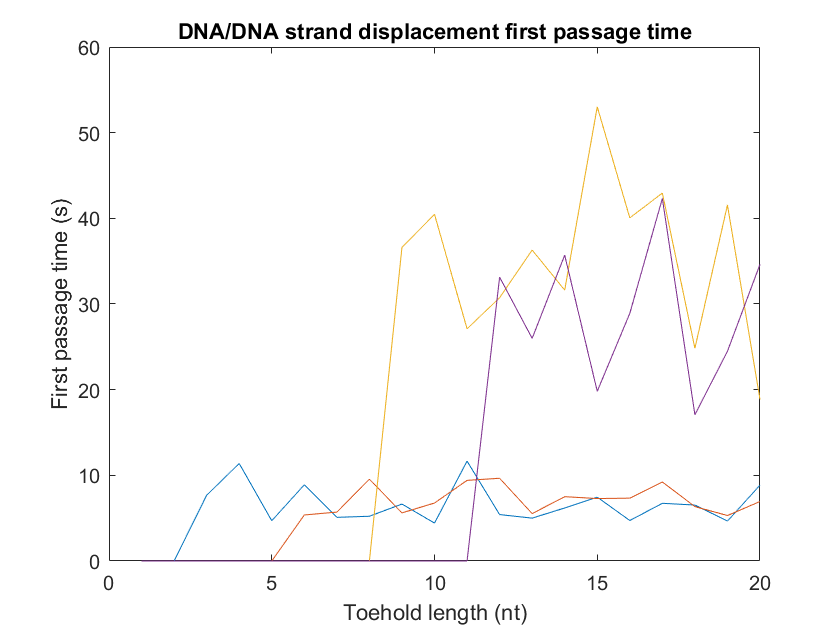

plot(1:20, avr_first_pass_time)
ylabel('First passage time (s)')
xlabel('Toehold length (nt)')
title('DNA/DNA strand displacement first passage time')

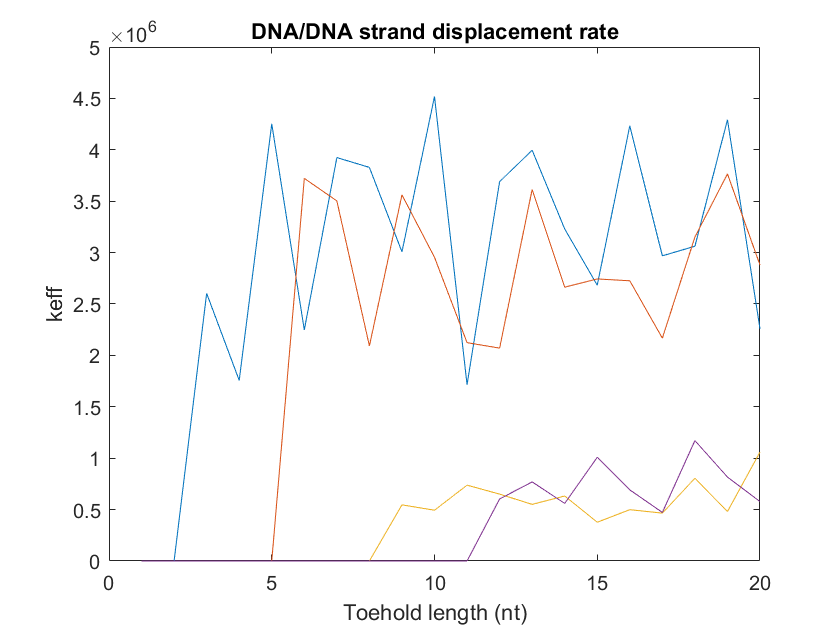


plot(1:20, k_eff)
ylabel('keff')
xlabel('Toehold length (nt)')
title('DNA/DNA strand displacement rate')

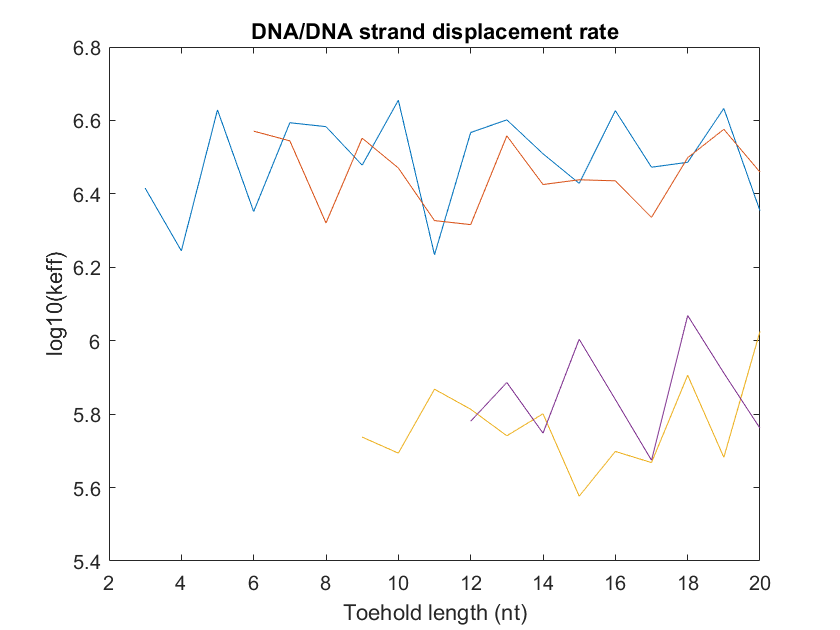


plot(1:20, log10(k_eff))
ylabel('log10(keff)')
xlabel('Toehold length (nt)')
title('DNA/DNA strand displacement rate')


for ind = 2:5
    errorbar(1:20, avr_first_pass_time, std_err_fpt(ind-1, :) , 'k', 'linewidth', 2)
    hold on
end

Error using errorbar>checkSingleInput (line 270)
XData must be the same size as YData.

Error in errorbar (line 94)
x = checkSingleInput(x, sz, 'XData');

plot(1:20, avr_first_pass_time, 'linewidth', 0.5)
xlabel('Branch migration domain length (nt)')
ylabel('First passage time (s)')
title('DNA/DNA strand displacement first passage time with toehold length of ' + string(g))

hold off

errorbar(1:20, k_eff, std_err_k_eff, 'k', 'linewidth', 2)
xlabel('Branch migration domain length (nt)')
ylabel('keff')
title('DNA/DNA strand displacement rate with toehold length of ' + string(g))
hold off

errorbar(1:20, log10(k_eff), std_err_log_k, 'k', 'linewidth', 2)
hold on
plot(1:20, log10(k_eff), '', 'linewidth', 0.5)
xlabel('Branch migration domain length (nt)')
ylabel('log10(keff)')
title('DNA/DNA strand displacement rate with toehold length of ' + string(g))
hold off